# 绘图复刻

## 分组柱状图

[MATLAB | 绘图复刻(一) | 分组柱状图 (qq.com)](https://mp.weixin.qq.com/s?__biz=Mzg4MTcwODk5Ng==&mid=2247490241&idx=1&sn=f2d486393a46c5d5c39c6e05378671fd&chksm=cf60806af817097c104d72729161089d936b130ba32afa008f1de80c0941132cab9f809884ff&scene=178&cur_album_id=2311130191869296643#rd)

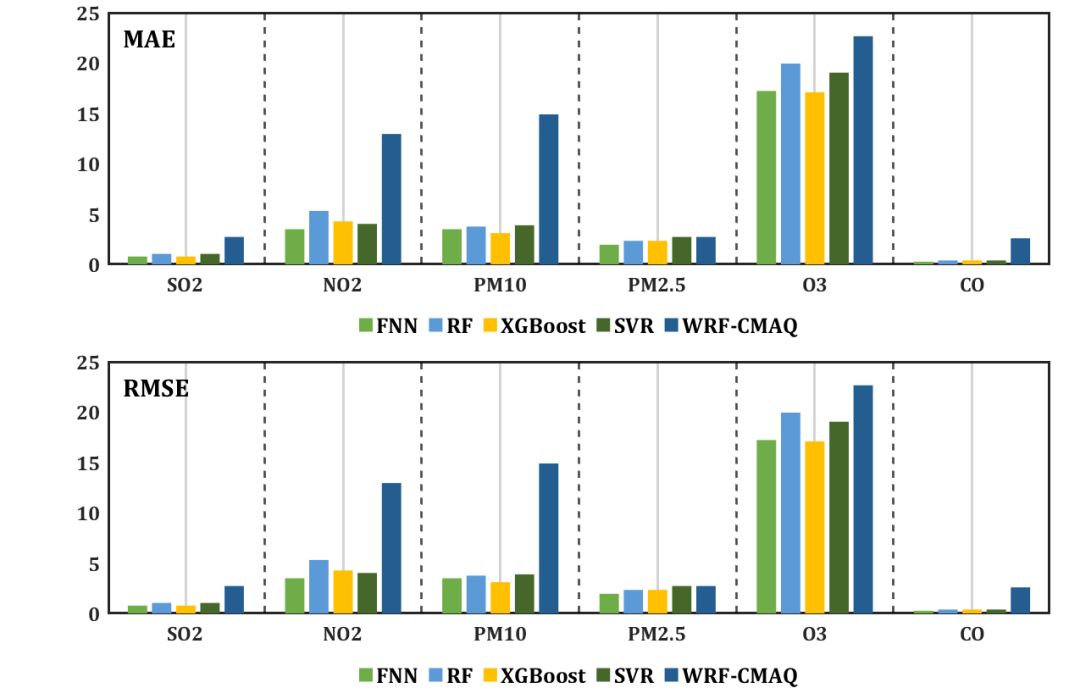

### 数据准备及子图绘制

随便构造了点数据，原图中上下子图是不同的数据，这边懒得改了直接用的相同的数据:

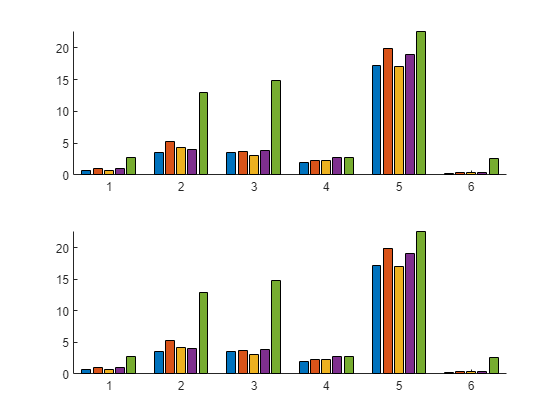

clc;clf;clear
% 自行构造的数据
YData=[0.7772    1.0363    0.7772    1.0363    2.7202;
       3.4974    5.3109    4.2746    4.0155   12.9534;
       3.4974    3.7565    3.1088    3.8860   14.8964;
       1.9430    2.3316    2.3316    2.7202    2.7202;
      17.2280   19.9482   17.0984   19.0415   22.6684;
       0.2591    0.3886    0.3886    0.3886    2.5907];
YData1=YData;YData2=YData;
% -------------------------------------------------------------------------
% 上子图
figure
ax1=subplot(2,1,1);hold on
hBar1=bar(YData1);

% 下子图
ax2=subplot(2,1,2);hold on
hBar2=bar(YData2); 

### 颜色准备及柱状图修饰

我之前在[MATLAB | 自制色卡、更改绘图配色、图像修饰 (qq.com)](https://mp.weixin.qq.com/s?__biz=Mzg4MTcwODk5Ng==&mid=2247485449&idx=1&sn=64096e74b4ac468a55b56f5f4ed7059e&chksm=cf6092a2f8171bb4fcedb58672a98061bbaa3d375b8e2e8ed3d9ad44bbf38c222a3dbd1712b2&scene=21#wechat_redirect)中给出过一个自写的颜色提取器，当然用qq颜色提取器甚至ppt取色器都行只要提取出颜色就好：

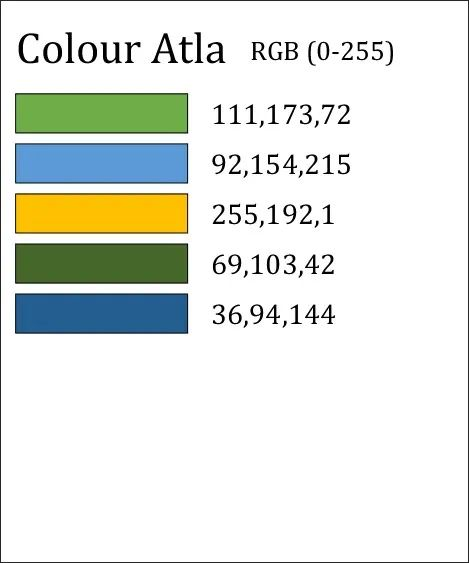

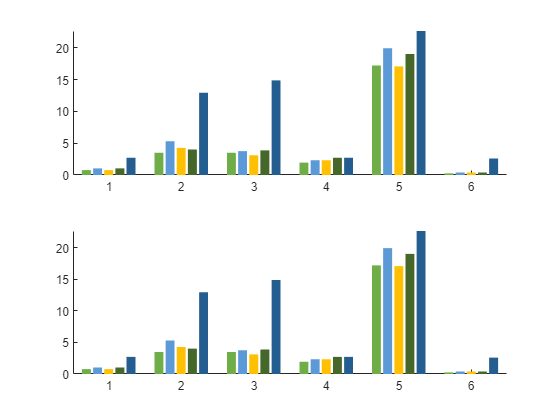

% 原图片配色(matlab要求配色范围0-1因此要除以255)
CData=[111,173,72;92,154,215;255,192,1;69,103,42;36,94,144]./255;
% -------------------------------------------------------------------------
% 分组柱状图修饰
for i=1:length(hBar1)
    hBar1(i).EdgeColor='none';      % 轮廓无色
    hBar1(i).FaceColor=CData(i,:);  % 设置颜色
    hBar2(i).EdgeColor='none';
    hBar2(i).FaceColor=CData(i,:);
end

### 坐标区域修饰

包括修改X轴标签文本，修改坐标区域字体，添加网格并修饰，框修饰，设置刻度长度等(详见注释)：

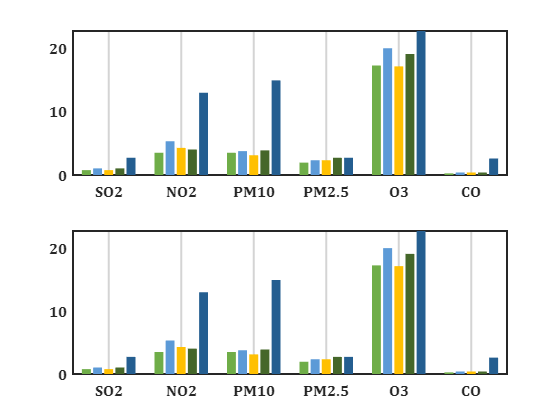


% 修改X轴标签文本
ax1.XTick=1:size(YData1,1);
ax2.XTick=1:size(YData2,1);
ax1.XTickLabel={'SO2','NO2','PM10','PM2.5','O3','CO'};
ax2.XTickLabel={'SO2','NO2','PM10','PM2.5','O3','CO'};
% 修改坐标区域字体
ax1.FontName='Cambria';
ax2.FontName='Cambria';
ax1.FontWeight='bold';
ax2.FontWeight='bold';
ax1.FontSize=12;
ax2.FontSize=12;
% 添加网格并修饰
ax1.XGrid='on';
ax2.XGrid='on';
ax1.GridAlpha=.2;
ax2.GridAlpha=.2;
% 框修饰
ax1.Box='on';
ax2.Box='on';
ax1.LineWidth=1.5;
ax2.LineWidth=1.5;
% 刻度长度设置为0
ax1.TickLength=[0,0];
ax2.TickLength=[0,0];

### 绘制辅助线(分组线)

图中有虚线将各组隔开，使用辅助线函数xline绘制：

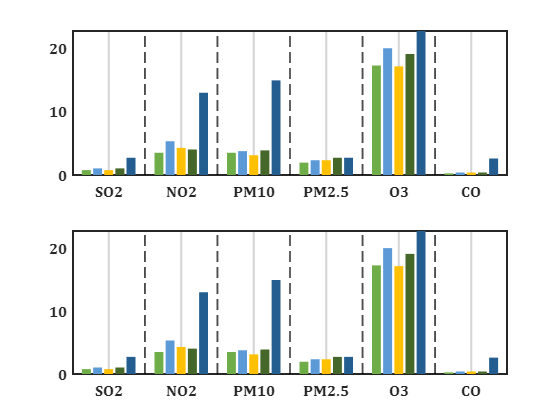


% 绘制辅助线
XV=(1:size(YData1,1)-1)+.5;
for i=1:length(XV)
    xline(ax1,XV(i),'LineWidth',1.4,'LineStyle','--','Color',[0,0,0]);
    xline(ax2,XV(i),'LineWidth',1.4,'LineStyle','--','Color',[0,0,0]);
end

### 添加图例并修饰

添加图例，去掉框，修改图标大小，更改位置，修改为多列:

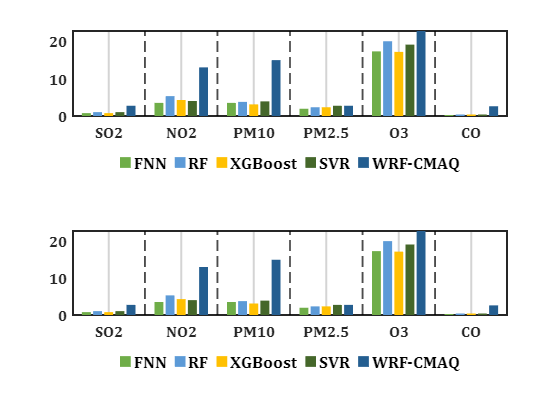


% 添加图例
lgd1=legend(hBar1,'FNN','RF','XGBoost','SVR','WRF-CMAQ','FontSize',13);
lgd2=legend(hBar2,'FNN','RF','XGBoost','SVR','WRF-CMAQ','FontSize',13);
% 设置图例位置
lgd1.Location='southoutside';
lgd2.Location='southoutside';
% 设置图例横向排列
lgd1.NumColumns=length(hBar1);
lgd2.NumColumns=length(hBar2);
% 设置图例方形大小
lgd1.ItemTokenSize=[8,8];
lgd2.ItemTokenSize=[8,8];
% 关闭框
lgd1.Box='off';
lgd2.Box='off';

### 调整比例

上一步添加图例导致比例有点和原图不像，这里调整一下(可省略这步)：

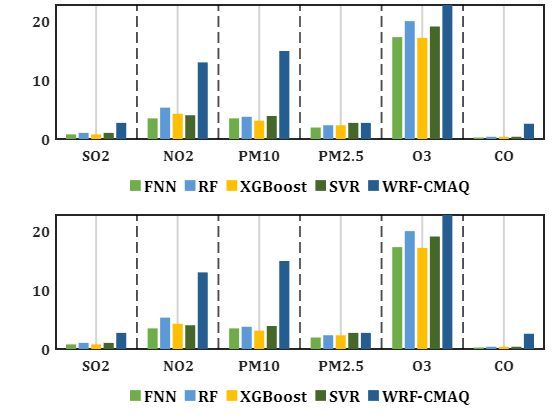


% 调整子图位置和比例
set(ax1,'LooseInset',[.1,0,0.028,0.03],'OuterPosition',[0,1/2-1/30,1,1/2+1/30]);
set(ax2,'LooseInset',[.1,0,0.028,0.03],'OuterPosition',[0,0-1/30,1,1/2+1/30]);

### 添加左上角标签

text函数绘制即可：

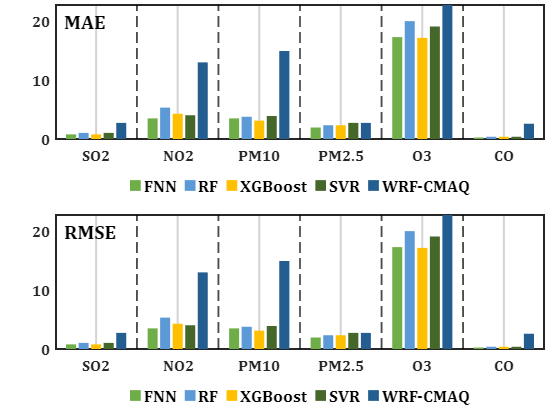


% 添加左上角标签
text(ax1,0.6,20,'MAE','FontSize',15,'FontWeight','bold','FontName','Cambria')
text(ax2,0.6,20,'RMSE','FontSize',15,'FontWeight','bold','FontName','Cambria')

## 藏在风景里的k线图

[MATLAB | 可视化 | 藏在风景里的k线图 (qq.com)](https://mp.weixin.qq.com/s?__biz=Mzg4MTcwODk5Ng==&mid=2247490415&idx=1&sn=b4513c101c53248b4ec6e91901a4ba8f&chksm=cf6081c4f81708d2e330fac8008a700df4fda63dc8a27c552c007ff6e09c448528b47b46838a&scene=178&cur_album_id=2311130191869296643#rd)

## 折线图+误差棒+柱状图+散点抖动+灰色背景+图片叠加

[MATLAB | 绘图复刻(二) | 折线图+误差棒+柱状图+散点抖动+灰色背景+图片叠加 (qq.com)](https://mp.weixin.qq.com/s?__biz=Mzg4MTcwODk5Ng==&mid=2247490498&idx=1&sn=270cd0a002664c2aa5d8e279dba583ac&chksm=cf608169f817087fe972b5da0854cc475336ca990e66fe239fc09a6f5ea34f5b4e046427f44a&scene=178&cur_album_id=2311130191869296643#rd)

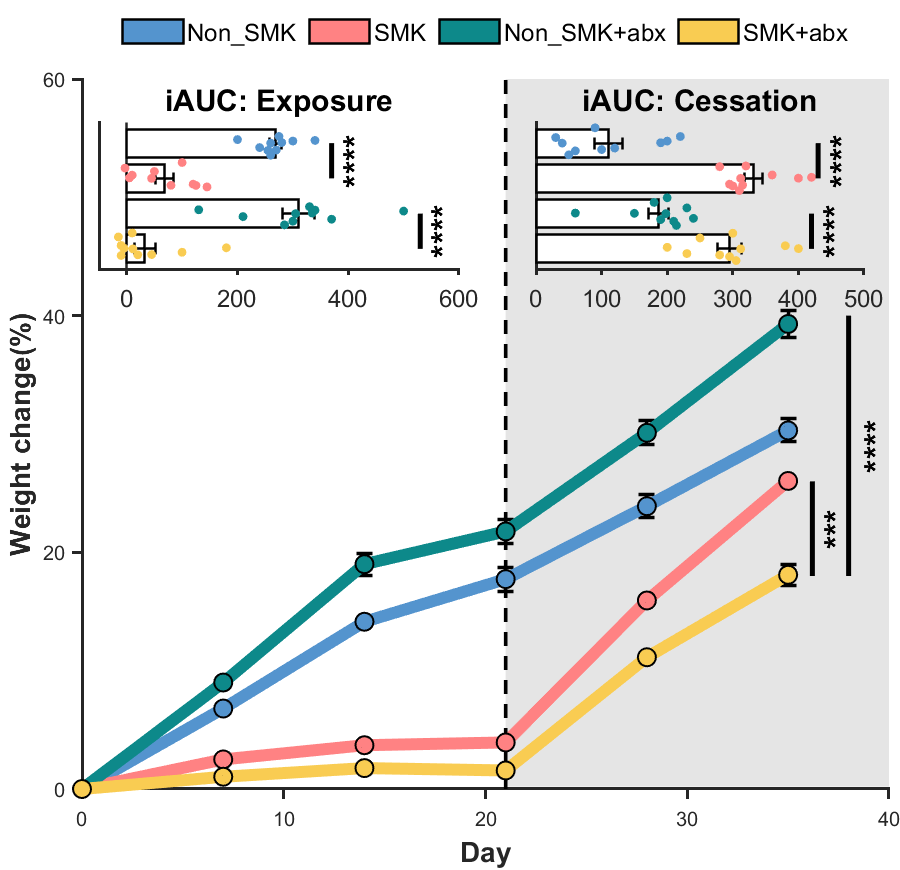

### 数据导入

由于数据不太规整，我们使用readtable读取table格式数据表，之后循环找到我们想要的数据。

clc;clear;close all
Data=readtable('2022.1.15.CSV','VariableNamingRule','preserve');
% 获取各组数据的名称
treatName=unique(Data.treat,'stable');

% 配色数据
colorList=[84,148,206;255,130,131;13,137,138;249,204,82]./255;

### 基础绘图

在循环内部使用errorbar绘制带误差棒折线图，同时由于误差棒边缘粗细颜色，和最前面折线图不同，因此每组数据还要分别再画两个plot折线图用来绘制粗线条和圆点，这里的误差使用的是SEM误差，即std/sqrt(n)：

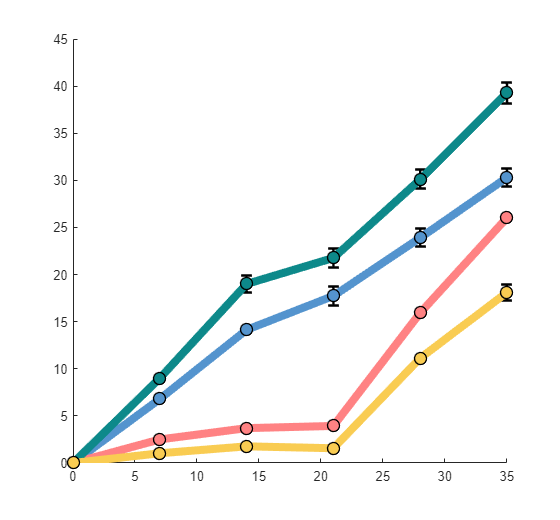

% -------------------------------------------------------------------------
% 创建图窗并获取坐标区域
figure('Position',[500,200,560,520])
ax=gca;hold on
for i=1:length(treatName)
    tempData=Data(strcmp(Data.treat,treatName{i}),:);
    % 将日期数据和value由table转换为array数组
    day=table2array(tempData(:,2));
    value=table2array(tempData(:,3:5));

    % 绘制含误差条的折线图、及粗折线图、及圆点图
    errorbar(day,mean(value,2),std(value,1,2)/sqrt(size(value,2)),...
        'Color',[0,0,0],'LineWidth',1.8,'Marker','o','CapSize',8);
    plot(day,mean(value,2),'Color',colorList(i,:),'LineWidth',6)
    plot(day,mean(value,2),'o','LineWidth',1,'MarkerEdgeColor',[0,0,0],...
        'MarkerFaceColor',colorList(i,:),'MarkerSize',9);
end

### 生成图例

图像中的图例不是圆点或者直线，而是一个长方形，看起来更像是patch对象的图例，因此需要把循环绘图部分修改一下，创造屏幕外的patch对象用来当作图例的图标，同时将图例的AutoUpdate设置为off以避免后续绘图图例自动更改：

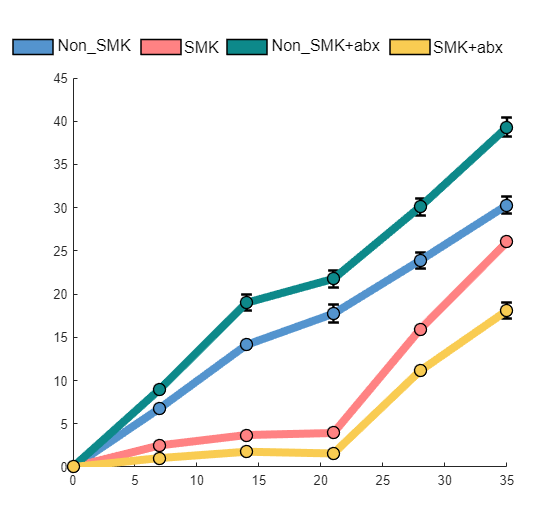

for i=1:length(treatName)
    tempData=Data(strcmp(Data.treat,treatName{i}),:);
    % 将日期数据和value由table转换为array数组
    day=table2array(tempData(:,2));
    value=table2array(tempData(:,3:5));

    % 绘制含误差条的折线图、及粗折线图、及圆点图
    errorbar(day,mean(value,2),std(value,1,2)/sqrt(size(value,2)),...
        'Color',[0,0,0],'LineWidth',1.8,'Marker','o','CapSize',8);
    plot(day,mean(value,2),'Color',colorList(i,:),'LineWidth',6)
    plot(day,mean(value,2),'o','LineWidth',1,'MarkerEdgeColor',[0,0,0],...
        'MarkerFaceColor',colorList(i,:),'MarkerSize',9);
    % 循环生成patch对象用来当作图例的图标
    patchHdl(i)=fill([0,0,0,0],[0,0,0,0],colorList(i,:),'LineWidth',1.2);
end
legend(patchHdl,{'Non\_SMK   ','SMK','Non\_SMK+abx','SMK+abx'},'AutoUpdate','off',...
    'Location','northoutside','NumColumns',4,'Box','off','FontSize',12)

### 增添灰色区域和常量线

就是用plot函数绘制直线，使用fill函数画灰色区域，并用uistack函数把这俩放在最下面，这里没用xline画常量线是因为推出较晚(R2018b)，且层级关系不好捋顺:

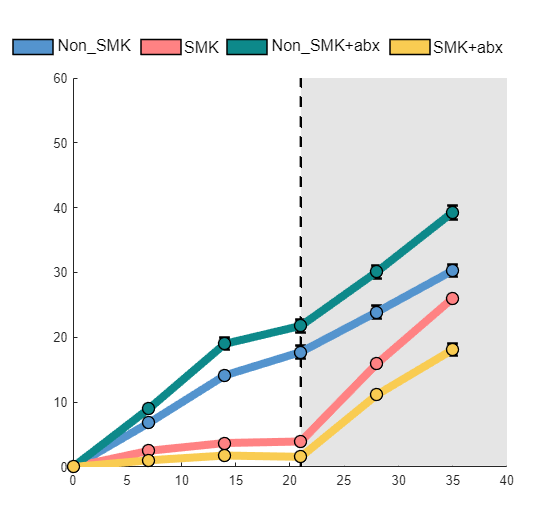


% 绘制区域分隔虚线,这里没用xline是因为推出较晚(R2018b)，且层级关系不好捋顺
xLineHdl=plot([21,21],[0,60],'LineWidth',1.8,'LineStyle','--','Color',[0,0,0]);
uistack(xLineHdl,'bottom')

% 绘制灰色区域并移动到最下方
grayAreaHdl=fill([21,21,40,40],[0+.2,60,60,0+.2],[229,229,229]./255,'EdgeColor','none');
uistack(grayAreaHdl,'bottom')

### 坐标区域修饰

调整坐标区域字体啊标签啊，横纵坐标比例等一系列元素，详细请看下面代码和注释：

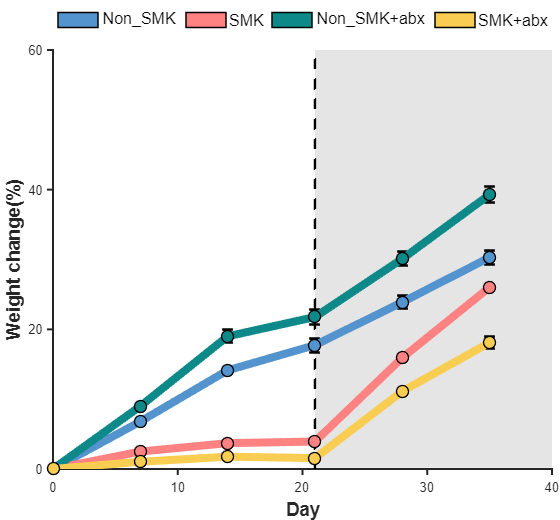

ax=gca;
% 调整边缘空间
ax.LooseInset=[0,0,0,0];
% 控制轴范围
ax.YLim=[0,60];
ax.XLim=[0,40];
ax.XTick=0:10:40;
ax.YTick=0:20:60;
% 修改xy轴标签和字体
ax.XLabel.String='Day';
ax.YLabel.String='Weight change(%)';
ax.XLabel.FontSize=14;
ax.YLabel.FontSize=14;
ax.XLabel.FontWeight='bold';
ax.YLabel.FontWeight='bold';
% 设置轴线粗细和刻度朝外
ax.LineWidth=1.5;
ax.TickDir='out';

### 添加显著性标记

提前算好显著性水平后就直接用plot和text添加标记就好了，不是很难：

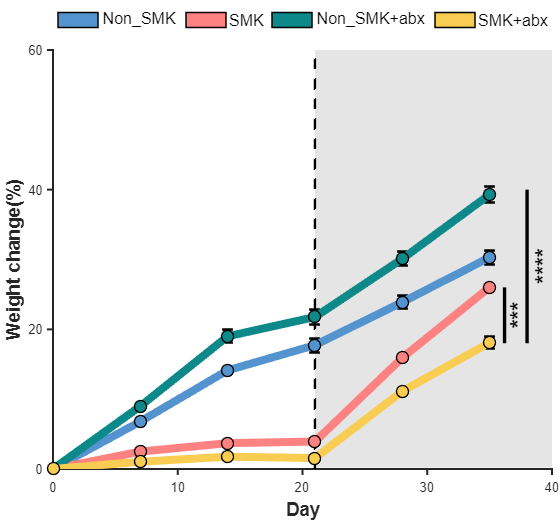

% 添加显著性标志
plot([36.2,36.2],[18,26],'Color',[0,0,0],'LineWidth',2.5)
plot([38,38],[18,40],'Color',[0,0,0],'LineWidth',2.5)
text(37.3,22,'***','Rotation',90,'FontSize',17,'HorizontalAlignment','center','FontWeight','bold')
text(39.3,29,'****','Rotation',90,'FontSize',17,'HorizontalAlignment','center','FontWeight','bold')

### 生成子图坐标区域

使用axes函数在当前图窗gcf生成俩新的坐标区域，设置背景色Color为透明none：

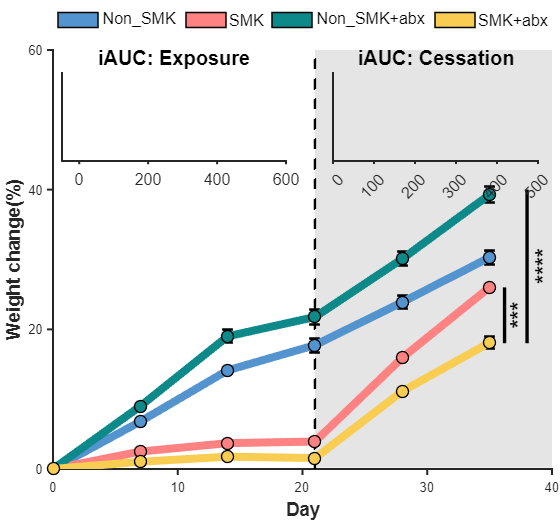


% 左上角坐标区域
ax2=axes(gcf,'Position',[.11,.69,.4,.17]);
hold on
ax2.XLim=[-50,600];
ax2.Color='none';
ax2.LineWidth=1.5;
ax2.TickDir='out';
ax2.FontSize=12;
ax2.XTick=0:200:600;
ax2.YTick=[];
ax2.Title.String='iAUC: Exposure';
ax2.Title.FontWeight='bold';
ax2.Title.FontSize=15;
ax2.YDir='reverse';
ax2.YLim=[.4,4.6];
% -------------------------------------------------------------------------
% 右上角坐标区域
ax3=axes(gcf,'Position',[.595,.69,.365,.17]);
hold on
ax3.XLim=[0,500];
ax3.Color='none';
ax3.LineWidth=1.5;
ax3.TickDir='out';
ax3.FontSize=12;
ax3.XTick=0:100:500;
ax3.YTick=[];
ax3.Title.String='iAUC: Cessation';
ax3.Title.FontWeight='bold';
ax3.Title.FontSize=15;
ax3.YDir='reverse';
ax3.YDir='reverse';
ax3.YLim=[.4,4.6];

### 柱状图绘制

比如在左侧ax2绘制柱状图，右侧ax3同理，同时因为0基线太细，我们要获取基线的句柄并将其加粗：

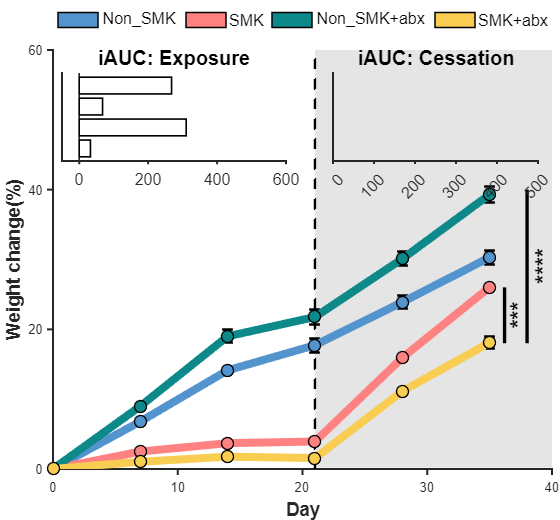


% 获取第一组柱状图数据并删除缺失值
barData1=[Data.Non_SMK,Data.SMK,Data.("Non_SMK+abx"),Data.("SMK+abx")];
barData1(isnan(barData1(:,1)),:)=[];
barHdl=barh(ax2,mean(barData1),'FaceColor',[1,1,1],'LineWidth',1.2,'EdgeColor',[0,0,0]);
% 设置0基线属性
barBaseLineHdl=barHdl.BaseLine;
barBaseLineHdl.LineWidth=1.2;

### 绘制柱状图误差条

还是使用errorbar函数，不过设置horizontal属性将其变为横向，同时设置LineStyle属性为none隐藏折线部分：

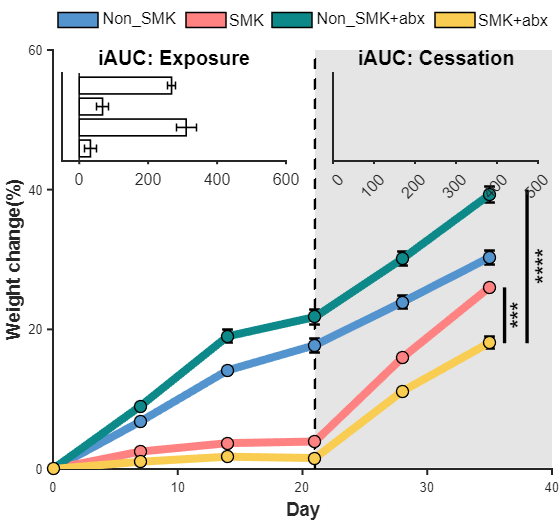


% 绘制误差条
errorbar(ax2,mean(barData1),1:4,std(barData1,1)./sqrt(size(barData1,1)),...
    'horizontal','LineStyle','none','LineWidth',1.2,'Color',[0,0,0])

### 绘制抖动散点

使用scatter绘制并设置YJitter抖动，不过该属性出现较晚，请使用R2020b及以后版本：

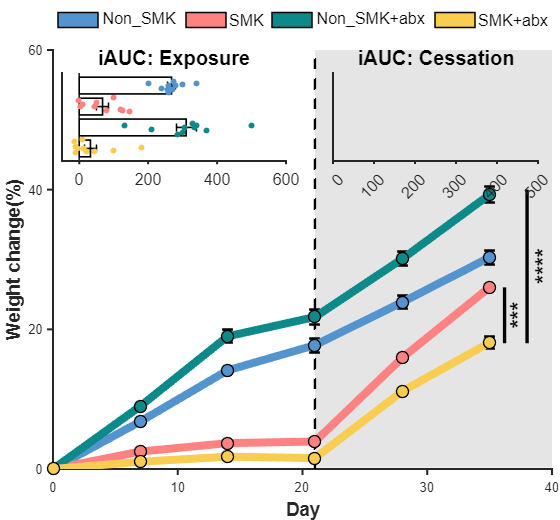


% 绘制抖动散点图
for i=1:4
    scatter(ax2,barData1(:,i),i.*ones(1,size(barData1,1)),20,...
        'filled','YJitter','density','CData',colorList(i,:))
end

### 绘制子图显著性标志

还是用plot和text绘制：

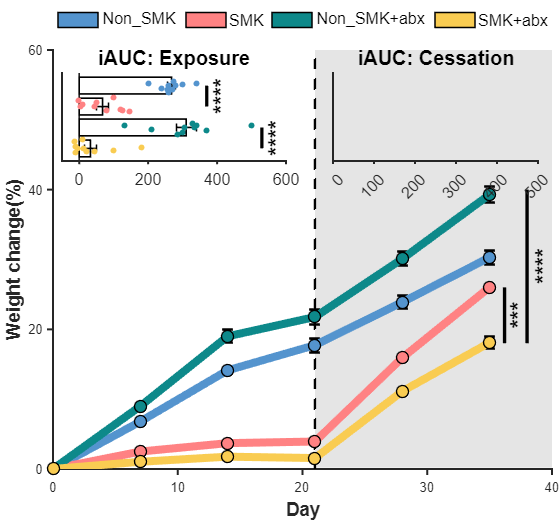


% 添加显著性标志
plot(ax2,[370,370],[1,2],'Color',[0,0,0],'LineWidth',2.5)
plot(ax2,[530,530],[3,4],'Color',[0,0,0],'LineWidth',2.5)
text(ax2,410,1.5,'****','Rotation',90,'FontSize',17,'HorizontalAlignment','center','FontWeight','bold')
text(ax2,570,3.5,'****','Rotation',90,'FontSize',17,'HorizontalAlignment','center','FontWeight','bold')

右上角子图

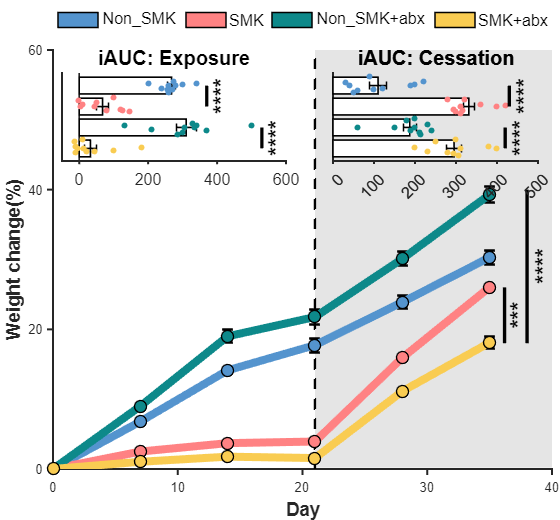

% 右上角坐标区域
ax3=axes(gcf,'Position',[.595,.69,.365,.17]);
hold on
ax3.XLim=[0,500];
ax3.Color='none';
ax3.LineWidth=1.5;
ax3.TickDir='out';
ax3.FontSize=12;
ax3.XTick=0:100:500;
ax3.YTick=[];
ax3.Title.String='iAUC: Cessation';
ax3.Title.FontWeight='bold';
ax3.Title.FontSize=15;
ax3.YDir='reverse';
ax3.YDir='reverse';
ax3.YLim=[.4,4.6];
% -------------------------------------------------------------------------
% 获取第一组柱状图数据并删除缺失值
barData2=[Data.Non_SMK_1,Data.SMK_1,Data.("Non_SMK+abx_1"),Data.("SMK+abx_1")];
barData2(isnan(barData2(:,1)),:)=[];
barHdl=barh(ax3,mean(barData2),'FaceColor',[1,1,1],'LineWidth',1.2,'EdgeColor',[0,0,0]);
% 设置0基线属性
barBaseLineHdl=barHdl.BaseLine;
barBaseLineHdl.LineWidth=1.2;
% 绘制误差条
errorbar(ax3,mean(barData2),1:4,std(barData2,1)./sqrt(size(barData2,1)),...
    'horizontal','LineStyle','none','LineWidth',1.2,'Color',[0,0,0])
% 绘制抖动散点图
for i=1:4
    scatter(ax3,barData2(:,i),i.*ones(1,size(barData2,1)),20,...
        'filled','YJitter','density','CData',colorList(i,:))
end
% % 老版本方案
% % 绘制抖动散点图
% for i=1:4
%     scatter(ax3,barData1(:,i),i+rand(1,size(barData2,1)).*.8-.4,20,...
%         'filled','YJitter','density','CData',colorList(i,:))
% end

% 添加显著性标志
plot(ax3,[430,430],[1,2],'Color',[0,0,0],'LineWidth',2.5)
plot(ax3,[420,420],[3,4],'Color',[0,0,0],'LineWidth',2.5)
text(ax3,465,1.5,'****','Rotation',90,'FontSize',17,'HorizontalAlignment','center','FontWeight','bold')
text(ax3,455,3.5,'****','Rotation',90,'FontSize',17,'HorizontalAlignment','center','FontWeight','bold')

## 罗密欧与朱丽叶的数据统计

[MATLAB | 可视化 | 罗密欧与朱丽叶的数据统计 (qq.com)](https://mp.weixin.qq.com/s?__biz=Mzg4MTcwODk5Ng==&mid=2247490513&idx=1&sn=0fb8ad30f9479b754d43090a2be80057&chksm=cf60817af817086c0f44b03f0475ede495d409f2ba5c5873e5a57c8c72c46b856bf6b7fee3e1&scene=178&cur_album_id=2311130191869296643#rd)

## 分层聚类分析图

[MATLAB | 绘图复刻(三) | 分层聚类分析图：树状图+热图 (qq.com)](https://mp.weixin.qq.com/s?__biz=Mzg4MTcwODk5Ng==&mid=2247490606&idx=1&sn=14e1c98724c11814d1258cedc91fb3e4&chksm=cf608685f8170f93bcd77b96c069b33c24d9632c62b0dbe6a41dc73f747f3738659ccd6c7050&scene=178&cur_album_id=2311130191869296643#rd)

## 和弦图

[MATLAB | 文末赠书 | 绘图复刻(四) | 和弦图+颜色修改+标签旋转 (qq.com)](https://mp.weixin.qq.com/s?__biz=Mzg4MTcwODk5Ng==&mid=2247490759&idx=1&sn=da893df9939e283e45c2bb17a561a8cd&chksm=cf60866cf8170f7aafc6bb77d9df1243a5ead17b44bd8835aef7f8c85a56dbc265997663e25e&scene=178&cur_album_id=2311130191869296643#rd)

## 带树状图的环形热图

[MATLAB | 绘图复刻(五) | 带树状图的环形热图 (qq.com)](https://mp.weixin.qq.com/s?__biz=Mzg4MTcwODk5Ng==&mid=2247491454&idx=1&sn=c42f91f1bd3eb1292eba0601589e290b&chksm=cf6085d5f8170cc3e0c7c46997e74f0860c5d5320efc70330253fb488bf70eb603e9fc127cb5&scene=178&cur_album_id=2311130191869296643#rd)

## 分组环形热图

[MATLAB | 绘图复刻(六) | 分组环形热图 (qq.com)](https://mp.weixin.qq.com/s?__biz=Mzg4MTcwODk5Ng==&mid=2247491505&idx=1&sn=959e704cdc69b936ac0dfb9d95e22c86&chksm=cf60851af8170c0c39a08c85e3086c80697d2c24639873831cda33c01b9ade679e3b90fa879b&scene=178&cur_album_id=2311130191869296643#rd)